# Chapter 17 Problem 94

Determine and plot, versus theta, the angular velocity of bar PQ and the linear velocity of mass P as general functions of the angle theta, given that Bar OQ has constant counter-clockwise angular velocity $\dot{\theta} = 2 $ rad/sec.

Discuss the locations of zero velocities in these plots. Do they make physical sense? Why or why not?

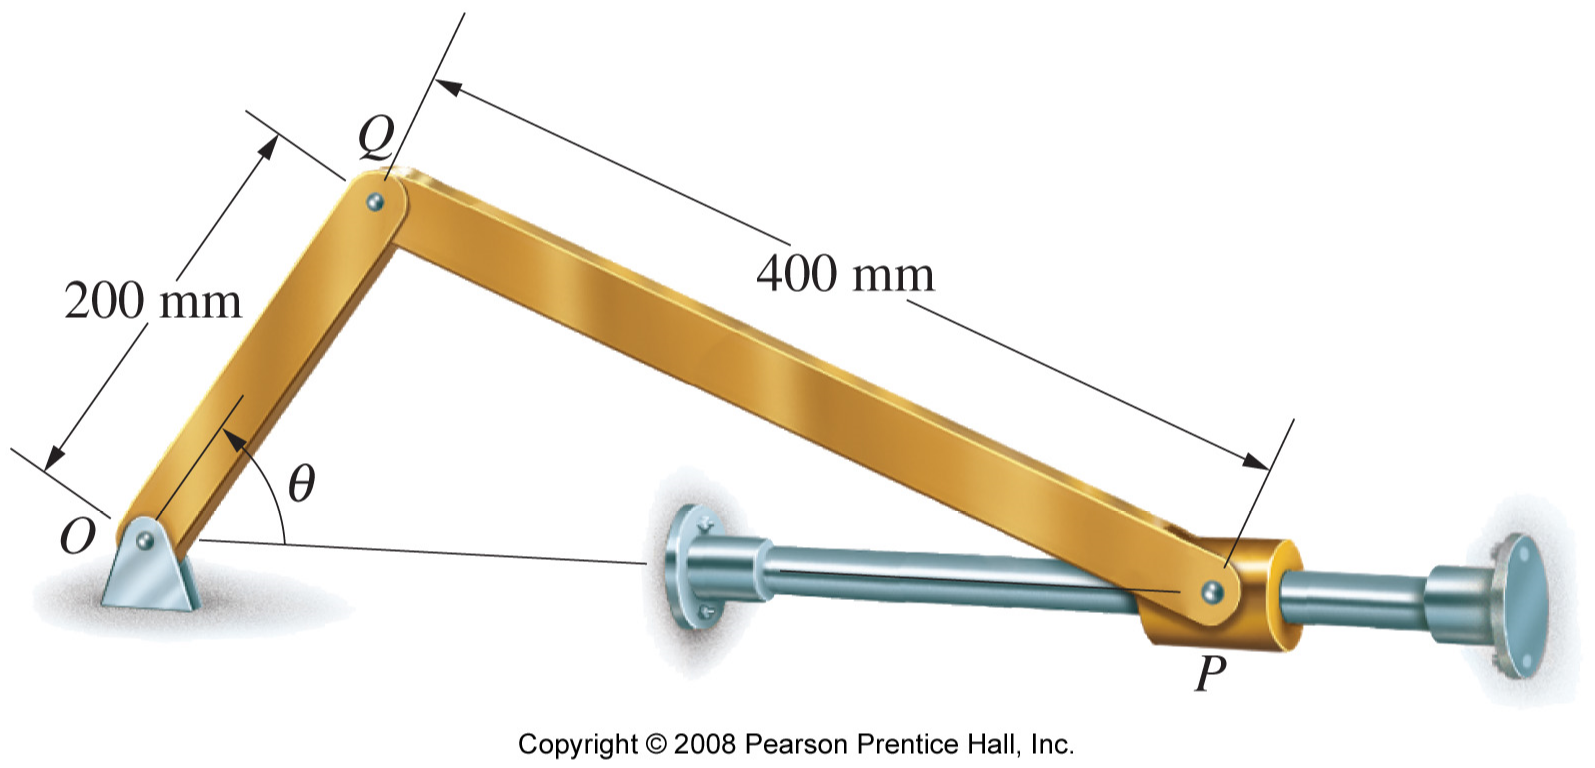

Define angles and bar lengths

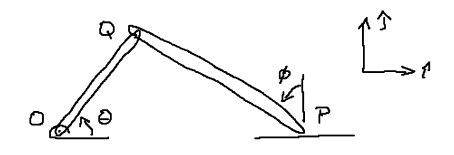

clc
clear
syms L_OQ L_QP theta theta_dot phi phi_dot v_P

## Find expressions for vP and phi_dot

v_Q = [0;0;0]+cross([0;0;theta_dot],L_OQ*[cos(theta);sin(theta);0]) == ...
    v_P*[1;0;0]+cross([0;0;phi_dot],L_QP*[-sin(phi);cos(phi);0])

$$v\_Q = \left(\begin{array}{c} -L_{\mathrm{OQ}}\,\dot{\theta }\,\sin\left(\theta \right)=v_{P}-L_{\mathrm{QP}}\,\dot{\varphi }\,\cos\left(\varphi \right)\\ L_{\mathrm{OQ}}\,\dot{\theta }\,\cos\left(\theta \right)=-L_{\mathrm{QP}}\,\dot{\varphi }\,\sin\left(\varphi \right)\\ 0=0 \end{array}\right)$$

unknowns = solve(v_Q,v_P,phi_dot);
v_P = unknowns.v_P

$$v\_P = -\frac{L_{\mathrm{OQ}}\,\dot{\theta }\,\left(\cos\left(\varphi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\theta \right)\right)}{\sin\left(\varphi \right)}$$

phi_dot = unknowns.phi_dot

$$phi\_dot = -\frac{L_{\mathrm{OQ}}\,\dot{\theta }\,\cos\left(\theta \right)}{L_{\mathrm{QP}}\,\sin\left(\varphi \right)}$$

eqn = L_QP*int(sin(phi),phi,pi/2,phi) == -L_OQ*int(cos(theta),theta,0,theta)

$$eqn = -L_{\mathrm{QP}}\,\cos\left(\varphi \right)=-L_{\mathrm{OQ}}\,\sin\left(\theta \right)$$

syms cp
cosphi = solve(subs(eqn,str2sym('cos(phi)'),cp),cp)

$$cosphi = \frac{L_{\mathrm{OQ}}\,\sin\left(\theta \right)}{L_{\mathrm{QP}}}$$

sinphi = sqrt(1-cosphi^2);
vP1 = simplify(subs(unknowns.v_P,[str2sym('sin(phi)'),str2sym('cos(phi)')],[sinphi,cosphi]));
phidot1 = simplify(subs(unknowns.phi_dot,str2sym('sin(phi)'),sinphi));

## Plot velocities

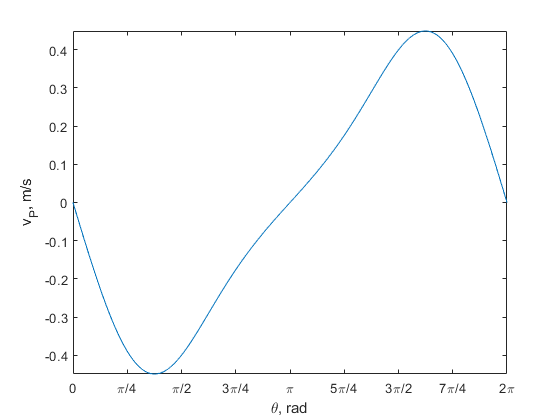

vPplot = subs(vP1,[L_OQ,L_QP,theta_dot],[0.2,0.4,2]);
phidotplot = subs(phidot1,[L_OQ,L_QP,theta_dot],[0.2,0.4,2]);
fplot(vPplot,[0,2*pi],'MeshDensity',360)
xlabel('\theta, rad')
ylabel('v_P, m/s')
set(gca,'XTick',0:pi/4:2*pi,'XTickLabel',...
    [{"0"},{"\pi/4"},{"\pi/2"},{"3\pi/4"},{"\pi"},{"5\pi/4"},{"3\pi/2"},{"7\pi/4"},{"2\pi"}])

The zero velocities occur when $\theta$ is 0 and $\pi$ radians. This makes physical sense since the farthest to the right the piston P can reach is when $\theta = 0$ radians and the farthest to the left the piston P can reach is when $\theta = \pi$radians.

The magnitude of the velocity of pin Q is $0.2 \text{m}\cdot 2 \text{rad/s} = 0.4 \text{m/s}$. It makes physical sense that the magnitude of the velocity of the piston P would also be on that same order of magnitude. It also makes sense that the maximum (and minimum) velocity of the piston P would be very close to the 0.4 m/s velocity of pin Q. In fact, at $\theta = \pi/2$ rad, since bar PQ is not rotating at that instant as its angular velocity changes from negative to positive, the velocity of the piston P is equal to the velocity of pin Q, -0.4 m/s. This is negative since pin Q and piston P are moving to the left. This occurs again at $\theta = 3\pi/2$ rad when point Q and piston P have positive, to the right, velocity 0.4 m/s.

To find min and max values of vP:

options = optimset('Display','off');
[thetamin,fmin] = fminunc(@(p)eval(subs(vPplot,theta,p)),pi/4,options);
fprintf('Minimum velocity of point P of %4.3f m/s occurs at an angle theta = %4.3f rad',fmin,thetamin)

Minimum velocity of point P of -0.449 m/s occurs at an angle theta = 1.182 rad

[thetamax,fmax] = fminunc(@(p)-eval(subs(vPplot,theta,p)),7*pi/4,options);
fprintf('Maximum velocity of point P of %4.3f m/s occurs at an angle theta = %4.3f rad',-fmax,thetamax)

Maximum velocity of point P of 0.449 m/s occurs at an angle theta = 5.102 rad

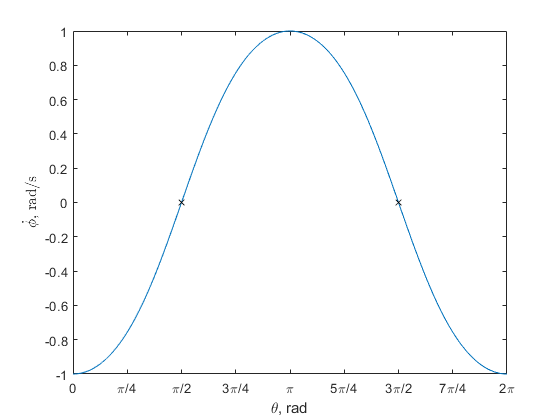

figure
fplot(phidotplot,[0,2*pi],'MeshDensity',360)
hold on
plot([pi/2,3*pi/2],[0,0],'xk')
xlabel('\theta, rad')
ylabel('$$\dot{\phi}$$, rad/s','Interpreter','latex')
set(gca,'XTick',0:pi/4:2*pi,'XTickLabel',...
    [{"0"},{"\pi/4"},{"\pi/2"},{"3\pi/4"},{"\pi"},{"5\pi/4"},{"3\pi/2"},{"7\pi/4"},{"2\pi"}])

In the plot for $\dot{\phi}$ we can see that the zero crossings occur at $\theta = \pi/2$ and $3\pi/2$ rad. This makes physical sense since the pin Q is at its maximum and minimum heights respectively. While $\theta$ is in quadrant 1, $\dot{\phi}$ must be negative as the bar rotates clockwise. While $\theta$ is in quadrant 2, $\dot{\phi}$ must be positive as the bar rotates counter-clockwise.While $\theta$ is in quadrant 2, $\dot{\phi}$ must also be positive as the bar continues to rotates counter-clockwise. Finally, while $\theta$ is in quadrant 4, $\dot{\phi}$ must be negative as the bar again rotates clockwise. At $\theta = 0$ the velocity of the pin Q is 0.4 m/s in the y-direction. Since the velocity of the piston P is zero at this instant, the velocity of Q on bar PQ must come from only the rotational velocity term. The length of bar PQ is 0.4 m thus the angular velocity must be 1 rad/sec in the clockwise direction to yield the same velocity magnitude and direction. A similar analysis shows that the angular velocity of bar PQ when $\theta = \pi$rad is 1 rad/sec.